# Load profile generation for EV stations

## Load profile generation for EV stations based on arrival/departure of vehicles

This work has been carried out for the BrainEN project. The development of this tool has its roots in the following paper:

*Daily EV Load Profile of an EV Charging Station at  Business Premises (2016) *

Blablabla...

clc
clearvars
close all

### Vehicle movement analysis

Declare the constant values for the vehicle movement curve generation

Ts = 1/4; % Timestep
dt = 0:Ts:24; % Time array
V_0 = 500; % Vehicles at t_0

Select type of arrival/departure curve based on the type of curve to generate. There are currently 2 options for the generation:

- Analytical: Based on gaussian distributions.

- Data: Based on empirical data.

type = "data";
switch type
    case "analytical"
        % Define the mean (start hour) and standard deviations
        [mean_arr, sig_arr] = deal(8, 3);
        [mean_dep, sig_dep] = deal(16, 4);
        % Establish the maximum number of vehicles arriving/leaving
        N_peak = 1000;
        % Build the EV movement curves
        arrivals = build_gaussian(dt, mean_arr, sig_arr, N_peak);
        departures = build_gaussian(dt, mean_dep, sig_dep, N_peak);
    case "data"
        % Build the EV movement curves from data
        file_arrivals = "Arrivals.csv";
        file_departures = "Departures.csv";
        arrivals = process_data_vehicles(file_arrivals, dt);
        departures = process_data_vehicles(file_departures, dt);
end

From the arrival/departure curves, we can build the vehicle movement curve knowing:


$$V_T \left(t\right)=V_T \left(t-T_s \right)-V_D \left(t\right)+V_A \left(t-T_s \right)$$


Vt_data = [V_0,...
    V_0 + cumsum(arrivals(1:end-1, 2) - departures(2:end, 2))'];
Vt = [dt', Vt_data'];

### Visualize results

Plot the vehicle movement data based on arrivals/departures of cars.

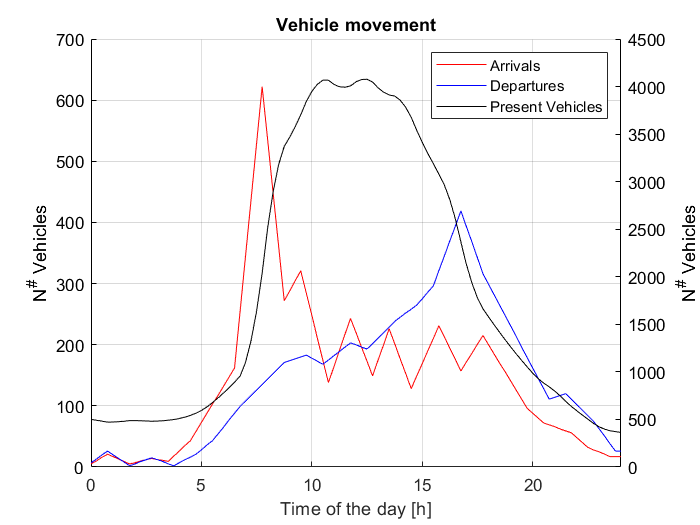

figure
hold on
grid on
title('Vehicle movement')
xlabel('Time of the day [h]')
yyaxis left
plot(arrivals(:,1), arrivals(:,2), '-r')
plot(departures(:,1), departures(:,2), '-b')
ylabel('N^# Vehicles')
yyaxis right
plot(Vt(:,1), Vt(:,2), '-k')
ylabel('N^# Vehicles')
ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';
xlim([0, 24])
legend('Arrivals', 'Departures', 'Present Vehicles')

### Auxiliary functions

Function to build the arrival/departure curves based on gaussian distributions

function proc=build_gaussian(dt, mu, sig, N_peak)
    % Construct a gaussian distribution curve for each time step
    gaussian = normpdf(dt, mu, sig);
    % Build car arrival/departure probability with the max number of cars
    R = rand(N_peak, length(gaussian)) < gaussian;
    % Aggregate the amount of cars each step
    proc = [dt', sum(R, 1)'];
end

Function to build the arrival/departure curves based on collected data

function proc=process_data_vehicles(file, dt)
    % Read the data from file
    data = readmatrix(file,...
        "Delimiter", ";", "DecimalSeparator", ",");
    % Process the data to discretize
    data(:, 1) = data(:, 1) - data(1,1);
    data(:, 1) = floor(data(:, 1)) +...
        floor( (data(:, 1)-floor(data(:, 1)))/0.25) * 0.25;
    data(:, 2) = round(data(:,2));
    % Build lacking timesteps by interpolation
    new = round(interp1(data(:, 1), data(:, 2), dt, "linear"));
    new(isnan(new)) = new(length(new(~isnan(new)))); % Fill NaN
    % Return the given profile
    proc = [dt', new'];
end